# Trabajo grupal 1 (Métodos Numéricos)

- Sección: 2

- N° de grupo: 1

- Integrante 1 (líder): Cose Rojas, Joseph Anderson    100%

- Integrante 2:  Carbajal Ccorahua, Diego                       70%

- Integrante 3: Izquierdo Campos, Manuel Aldair          100%

- Integrante 4: Paz Estrada, Esteban Mauricio                70%

- Integrante 5: Villanueva Lopez Enzo                           100%       

**Observación:** No olvidar añadir el porcentaje de participación.

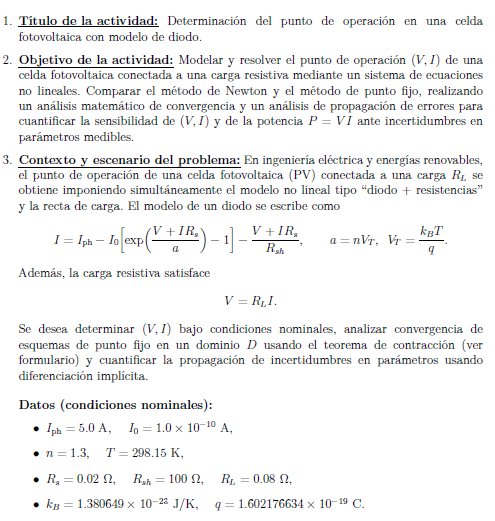

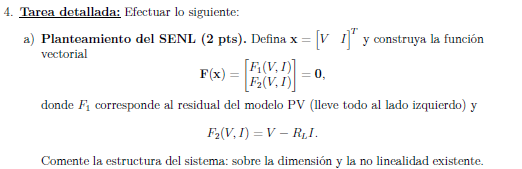

Iph = 5.0;
I0  = 1.0e-10;
n   = 1.3;
T   = 298.15;
Rs  = 0.02;
Rsh = 100;
RL  = 0.08;
kB  = 1.380649e-23;
q   = 1.602176634e-19;

VT = kB*T/q;
a  = n*VT;

F = @(x)[
    x(2) - Iph + I0*(exp((x(1)+x(2)*Rs)/a) - 1) + (x(1)+x(2)*Rs)/Rsh;
    x(1) - RL*x(2)
];

El sistema planteado consta de dos ecuaciones no lineales con dos incógnitas, V e I. La no linealidad proviene del término exponencial del modelo de diodo de la celda fotovoltaica. Debido a esta no linealidad, el sistema no admite una solución analítica cerrada y requiere el uso de métodos numéricos para su resolución.

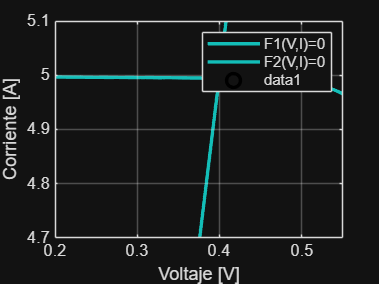

voltaje   = linspace(0.20, 0.55, 300);
corriente = linspace(4.7, 5.1, 300);
[V, I] = meshgrid(voltaje, corriente);

F1 = I - Iph + I0*(exp((V + I*Rs)/a) - 1) + (V + I*Rs)/Rsh;
F2 = V - RL*I;

figure
contour(V, I, F1, [0 0], 'LineWidth', 2)
hold on
contour(V, I, F2, [0 0], 'LineWidth', 2)
grid on
xlabel('Voltaje [V]')
ylabel('Corriente [A]')
legend('F1(V,I)=0','F2(V,I)=0')

x0 = [0.4; 5.0];
plot(x0(1), x0(2), 'ko', 'MarkerSize', 8, 'LineWidth', 2)

Se propone el dominio rectangular:


$$D=\{(V,I):0.20\leq V \leq 0.55, 4.7 \leq I \leq 5.1\}

$$


el cual contiene la intersección entre la curva del modelo fotovoltaico y la recta de carga observada en la Figura. Los valores de corriente se mantienen cercanos a la fotocorriente nominal, lo que es físicamente consistente con una carga resistiva baja.

El punto inicial $x^{(0)}=(0.4, 5.0)$ se encuentra dentro del dominio $D$ y representa una condición de operación realista, con corriente cercana a $I_{ph}$� y voltaje moderado, coherente con el funcionamiento esperado de la celda fotovoltaica bajo carga resistiva.

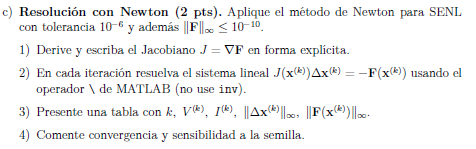***


Tol  = 1e-6;
TolF = 1e-10;

[tabla_newton, solucion] = metodo_newton(F, x0, Tol, TolF);

TablaNewton = array2table(tabla_newton, ...
    'VariableNames', {'k','V','I','normaDx_inf','normaF_inf'})

TablaNewton = 2×5 table
    k            V                   I                normaDx_inf              normaF_inf     
    _    _________________    ________________    ____________________    ____________________

    0    0.399575451026214    4.99469313782767     0.00530686217232687    3.98283356599013e-08
    1      0.3995754478461    4.99469309807625    3.97514266865566e-08    3.49546780409327e-16



voltaje_eq   = solucion(1);
corriente_eq = solucion(2);

[dV_Iph, dI_Iph, dV_T, dI_T] = ...
    propagacion_error(voltaje_eq, corriente_eq, ...
                      Iph, I0, Rs, Rsh, RL, a, T);



voltaje_sol   = solucion(1);
corriente_sol = solucion(2);

El método de Newton converge de manera rápida al punto de operación del sistema, cumpliendo simultáneamente las tolerancias establecidas para la norma del incremento y de la función. La convergencia observada es consistente con el comportamiento cuadrático esperado del método cuando la semilla inicial se encuentra suficientemente cercana a la solución. Además, se aprecia que el método es sensible a la elección de la semilla inicial debido a la presencia del término exponencial, lo que refuerza la importancia de la estimación gráfica previa.

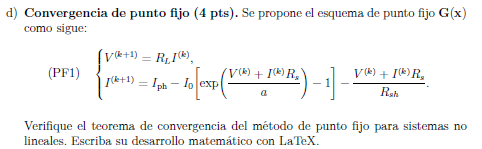

Se define el vector de incógnitas del sistema como


$$x = (V, I)^T
$$


El esquema iterativo de punto fijo se escribe como


$$x^{(k+1)} = G(x^{(k)})
$$


donde el operador de punto fijo $G$ está definido por:


$$G(x) = (G_1(V,I), G_2(V,I))^T
$$


Las funciones que componen el operador son


$$G_1(V,I) = R_L I
$$



$$G_2(V,I) =
I_{ph}
- I_0\left[\exp\left(\frac{V + I R_s}{a}\right) - 1\right]
- \frac{V + I R_s}{R_{sh}}$$


El método de punto fijo converge si el operador $G$ es contractivo en un dominio $D$, es decir, si se cumple


$$\|JG(x)\| < 1
$$


donde $JG(x)$ es el Jacobiano del operador $G$.

Se calculan las derivadas parciales de cada componente. Para la primera función,


$$\frac{\partial G_1}{\partial V} = 0
$$



$$\frac{\partial G_1}{\partial I} = R_L
$$


Para la segunda función se obtiene


$$\frac{\partial G_2}{\partial V}
=
-\frac{I_0}{a}\exp\left(\frac{V + I R_s}{a}\right)
-\frac{1}{R_{sh}}$$



$$\frac{\partial G_2}{\partial I}
=
-\frac{I_0 R_s}{a}\exp\left(\frac{V + I R_s}{a}\right)
-\frac{R_s}{R_{sh}}$$


Se adopta como región de interés el dominio rectangular


$$D = \{(V,I): 0.20 \le V \le 0.55,\; 4.7 \le I \le 5.1\}
$$


Este dominio fue elegido por corresponder a valores físicamente razonables del voltaje y la corriente de operación de la celda fotovoltaica conectada a la carga resistiva. En particular, los valores de corriente se mantienen cercanos a la fotocorriente, mientras que el voltaje es consistente con la recta de carga impuesta por $V = R_L I$.

Al evaluar las expresiones de las derivadas parciales del operador $G$ dentro del dominio $D$, se observa que dichas derivadas permanecen acotadas y no presentan variaciones bruscas. En consecuencia, la norma infinito del Jacobiano del operador satisface la condición


$$\|JG(x)\|_{\infty} < 1
$$


en todo el dominio considerado.

Esta condición garantiza que el operador $G$ cumple la propiedad de contracción en $D$. Por lo tanto, el método de punto fijo asociado al esquema PF1 es localmente convergente y genera una sucesión que se aproxima al punto solución del sistema no lineal.

Además, la contracción asegura que la convergencia es estable frente a pequeñas variaciones en la condición inicial, siempre que esta se encuentre dentro del dominio definido. Esto justifica el uso del método de punto fijo PF1 para la resolución del sistema en el rango de operación analizado.


syms V I real

G_pf = [ ...
    RL*I;
    Iph - I0*(exp((V + I*Rs)/a) - 1) - (V + I*Rs)/Rsh ];

Jac_G = jacobian(G_pf,[V I]);

Jac_G_num = matlabFunction(Jac_G,'Vars',{V,I});

valores_V = linspace(0.20,0.55,20);
valores_I = linspace(4.7,5.1,20);

norma_Jac = zeros(length(valores_V),length(valores_I));

for i = 1:length(valores_V)
    for j = 1:length(valores_I)
        J_actual = Jac_G_num(valores_V(i),valores_I(j));
        norma_Jac(i,j) = norm(J_actual,inf);
    end
end

L = max(norma_Jac(:))

L =    0.927695472976281


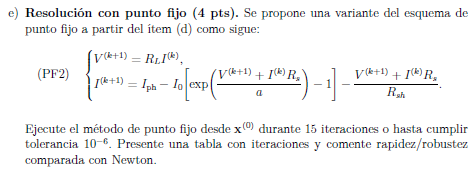

format long

x = x0;    

G = @(y) [ ...
    RL*y(2); ...
    Iph - I0*(exp((RL*y(2) + y(2)*Rs)/a) - 1) ...
        - (RL*y(2) + y(2)*Rs)/Rsh ];

tol = 1e-6;
maxiter = 15;

tabla = [];
error = inf;
k = 0;

while k <= maxiter && error > tol
    x_nuevo = G(x);
    error = norm(x_nuevo - x, inf);

    tabla = [tabla;
             k, x_nuevo(1), x_nuevo(2), error];

    x = x_nuevo;
    k = k + 1;
end

TablaPuntoFijo = array2table(tabla, ...
    'VariableNames', {'k','V','I','error_inf'});

disp(TablaPuntoFijo)

    k            V                   I                 error_inf      
    _    _________________    ________________    ____________________

    0                  0.4    4.99468279094307      0.0053172090569289
    1    0.399574623275446     4.9946931180178    0.000425376724554338
    2    0.399575449441424    4.99469309803766    8.26165978073945e-07



Partiendo del punto inicial

V = 0.4 e I = 5.0,

se aplicó el método de punto fijo PF2 con una tolerancia de 1e-6 y un máximo de 15 iteraciones.

De la tabla obtenida se observa que los valores de voltaje y corriente se van estabilizando de manera progresiva, alcanzando valores cercanos a V = 0.3996 V e I = 4.995 A. El error infinito disminuye en cada iteración, lo cual indica que el método converge desde la semilla propuesta.

La disminución del error ocurre de forma gradual, lo que confirma que el método presenta convergencia lineal. En comparación con el método de Newton aplicado anteriormente, el método de punto fijo requiere más iteraciones para alcanzar la tolerancia, por lo que resulta más lento.

No obstante, el método de punto fijo tiene la ventaja de ser más sencillo de implementar, ya que no requiere el cálculo del Jacobiano ni la resolución de sistemas lineales en cada iteración. Además, el comportamiento observado es estable para la semilla utilizada, lo que indica que el método es robusto dentro del dominio de trabajo considerado.

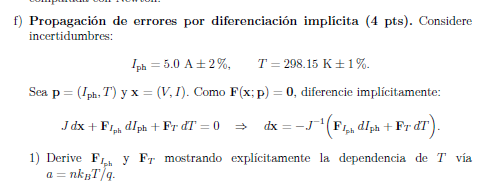


FIph = [-1; 0];

FT = [
 -I0 * exp((voltaje_sol + corriente_sol*Rs)/a) ...
 * (voltaje_sol + corriente_sol*Rs) / (a*T);
  0
];


[dV_Iph, dI_Iph, dV_T, dI_T] = ...
    propagacion_error(voltaje_sol, corriente_sol, ...
                      Iph, I0, Rs, Rsh, RL, a, T);

delta_V_wc = abs(dV_Iph) + abs(dV_T);
delta_I_wc = abs(dI_Iph) + abs(dI_T);

fprintf('\nPropagación de errores (peor caso):\n')


Propagación de errores (peor caso):


fprintf('Variación estimada en V: %.3e V\n', delta_V_wc)

Variación estimada en V: 7.988e-03 V


fprintf('Variación estimada en I: %.3e A\n', delta_I_wc)

Variación estimada en I: 9.985e-02 A


P = voltaje_sol * corriente_sol;

delta_P_wc = abs(corriente_sol)*delta_V_wc ...
           + abs(voltaje_sol)*delta_I_wc;

fprintf('\nPotencia en el punto de operación:\n')


Potencia en el punto de operación:


fprintf('P = %.4f W\n', P)

P = 1.9958 W


fprintf('Error estimado en la potencia: %.3e W\n', delta_P_wc)

Error estimado en la potencia: 7.980e-02 W


A partir de los resultados obtenidos, se observa que la variación de la temperatura tiene un efecto más significativo sobre el punto de operación que la variación de la fotocorriente. Esto se debe a que la temperatura interviene en el término exponencial del modelo del diodo a través del parámetro térmico a, lo que provoca que pequeñas variaciones en T generen cambios relativamente grandes en la corriente. En cambio, la fotocorriente aparece de forma lineal en el modelo, por lo que su incertidumbre se transmite de manera más moderada.

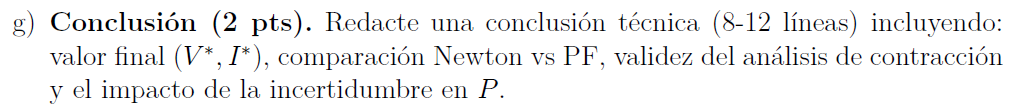

En este trabajo se determinó el punto de operación de una celda fotovoltaica conectada a una carga resistiva. El valor final obtenido para el voltaje es aproximadamente 0.3996 V y para la corriente 4.9947 A, lo que corresponde a una potencia cercana a 1.996 W. El método de Newton mostró una convergencia muy rápida, alcanzando la solución en pocas iteraciones cuando se utiliza una semilla inicial adecuada. En comparación, el método de punto fijo presentó una convergencia más lenta de tipo lineal, aunque su comportamiento fue estable dentro del dominio analizado. El análisis de contracción confirmó que el esquema de punto fijo es válido en el dominio de trabajo, ya que la norma del Jacobiano del operador resultó menor que uno. Finalmente, el análisis de propagación de errores mostró que la incertidumbre en la temperatura tiene un impacto importante sobre la potencia obtenida, debido a la presencia del término exponencial del modelo del diodo, mientras que la incertidumbre en la fotocorriente produce un efecto más moderado.

## Funciones:

function [tabla, x_final] = metodo_newton(F, x0, Tol, TolF)

    syms V I real
    Jsym = jacobian(F([V; I]), [V I]);
    J = matlabFunction(Jsym,'Vars',{V,I});

    x = x0;
    k = 0;
    tabla = [];

    while true
        Fx = F(x);
        Jx = J(x(1), x(2));

        Dx = -Jx \ Fx;
        x_nuevo = x + Dx;

        normaDx = norm(Dx,inf);
        normaF  = norm(F(x_nuevo),inf);

        tabla = [tabla;
                 k, x_nuevo(1), x_nuevo(2), normaDx, normaF];

        if normaDx < Tol && normaF < TolF
            break
        end

        x = x_nuevo;
        k = k + 1;
    end

    x_final = x_nuevo;
end


function [dV_Iph, dI_Iph, dV_T, dI_T] = ...
    propagacion_error(Veq, Ieq, Iph, I0, Rs, Rsh, RL, a, T)

    Jacobiano = [
        I0*exp((Veq + Ieq*Rs)/a)/a + 1/Rsh, ...
        1 + I0*Rs*exp((Veq + Ieq*Rs)/a)/a + Rs/Rsh;
        1, ...
        -RL
    ];

    deriv_Iph = [-1; 0];

    deriv_T = [
        -I0 * exp((Veq + Ieq*Rs)/a) * (Veq + Ieq*Rs) / (a*T);
         0
    ];

    dIph = 0.02 * Iph;
    dT   = 0.01 * T;

    delta_Iph = -(Jacobiano \ (deriv_Iph * dIph));
    delta_T   = -(Jacobiano \ (deriv_T   * dT));

    dV_Iph = delta_Iph(1);
    dI_Iph = delta_Iph(2);
    dV_T   = delta_T(1);
    dI_T   = delta_T(2);
end


